num=1;
den=[1 10 20];
g=tf(num,den)


g =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.



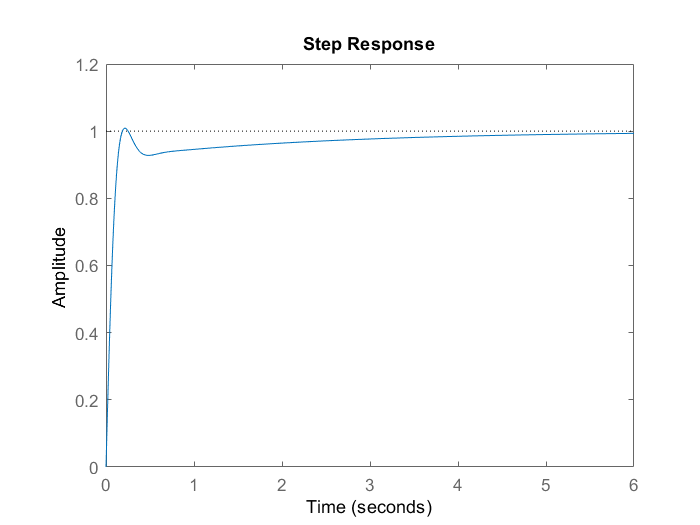

t=feedback(g,1);


kp=200;
ki=90;
kd=10;
cont=pid(kp,ki,kd);
step(feedback(cont*t,1));

stepinfo(feedback(cont*t,1))

ans = struct with fields:
        RiseTime: 0.1185
    SettlingTime: 3.3587
     SettlingMin: 0.9097
     SettlingMax: 1.0090
       Overshoot: 0.8999
      Undershoot: 0
            Peak: 1.0090
        PeakTime: 0.2164


k=dcgain(cont*t);
1/(1+k)

ans = 0